# High-Dimensional Estimation

This script uses a nearest neighbor method to calculate multi-dimensional mutual information.

## Initialize Workspace

% Clear everything:
clear all; close all force; clc;

% Path maintenance:
restoredefaultpath
addpath('matlab_tools')
addpath('project_tools')

% Initialize plotting:
fignum = 0;
colors = grab_plot_colors;

## Step 1: Create and Plot a Synthetic Mixture Density

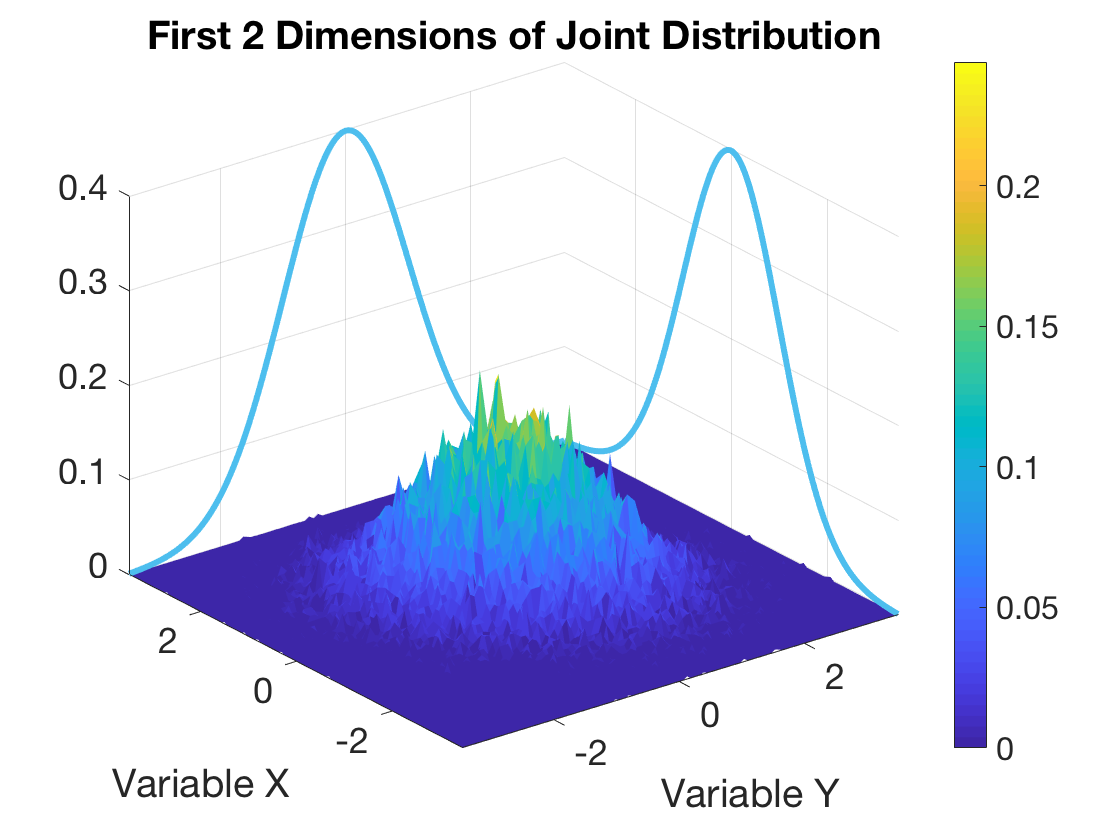

% How many marginals?
nMarginals = 4;

% How many kernels?
nKernels = 1;

% Which type(s) of kernel to use?
kernelType = 'Normal';

% Choose copula strength (only used in the case of a bivariate normal):
copulaCorrelation = 0.8;

% How many samples?
logSamples = 4.8;
nSamples = round(10^logSamples);

% How many histogram bins?
nBins = 100;

% Create joint densities:
jointDensity = create_joint_density(nKernels,kernelType,nMarginals,copulaCorrelation);

% The section for sampling and plotting a joint distribution is
% condensed to a single function to save space in this live script.
fignum = fignum+1;
sample = section_sample_and_plot_joint(jointDensity,nSamples,nBins,fignum);

## Step 2: Convergence of Estimators

% Sample sizes to test:
nSampleSizes = 10;      % number of sample sizes
maxSampleSize = 3.3;      % maximum sample size
sampleSizes = unique(round(logspace(1,maxSampleSize,nSampleSizes)));
nSampleSizes = length(sampleSizes);

% How to split dimensions:
xMarginals = 0.6;
xMarginals = max(min(nMarginals-1,round(nMarginals*xMarginals)),1);
yMarginals = nMarginals - xMarginals;

% Number of neighborhood sizes:
nNeighbors = 5;
maxNeighbors = 15;
neighbors = unique(round(logspace(0,log10(maxNeighbors),nNeighbors)));
nNeighbors = length(neighbors);

% Number of resampling experiments:
nResamples =1;

% True value in special case:
iTrue = 0/0;
if nKernels == 1 && strcmpi(kernelType,'Normal') && nMarginals == 2
    Rx = jointDensity.copulaCovariance(1:xMarginals,1:xMarginals);
    Ry = jointDensity.copulaCovariance(1+xMarginals:end,1+xMarginals:end);
    R = jointDensity.copulaCovariance;
    iTrue = 1/2 * log(det(Rx)*det(Ry)/det(R));
end

% Initialize storage (nearest neighbors):
ikNN    = zeros(nSampleSizes,nNeighbors,nResamples)./0;
hxkNN   = zeros(nSampleSizes,nNeighbors,nResamples)./0;
hykNN   = zeros(nSampleSizes,nNeighbors,nResamples)./0;

% container to control screen output
if 1
    
    % Initialize progress bar:
    fprintf('Sampling ... \n');
    fprintf(strcat(repmat('.',[1,nResamples*nSampleSizes]),'\n')); tic;
    
    % loop through resampling experiments:
    for r = 1:nResamples
        
        % Loop through sample sizes and bin counts:
        for s = 1:nSampleSizes
            
            % Draw a sample:
            sample = sample_joint_density(jointDensity,sampleSizes(s));
            X = sample(:,1);
            Y = sample(:,2);
            
            % perform calcualtion for different neighborhoods
            for k = 1:nNeighbors
                if sampleSizes(s) >= neighbors(k) * 10
                    [ikNN(s,k,r),hxkNN(s,k,r),hykNN(s,k,r)] = knn_info(X,Y,neighbors(k));
                end
            end

            % screen report
            fprintf('.');          
            
        end % s-loop
    end % r-loop
    
    % Screent report:
    fprintf('time = %f[s] \n',toc);
    
end % container for screen report

Sampling ... 


..........


..........

time = 6.966734[s] 


## Step 3: Plot

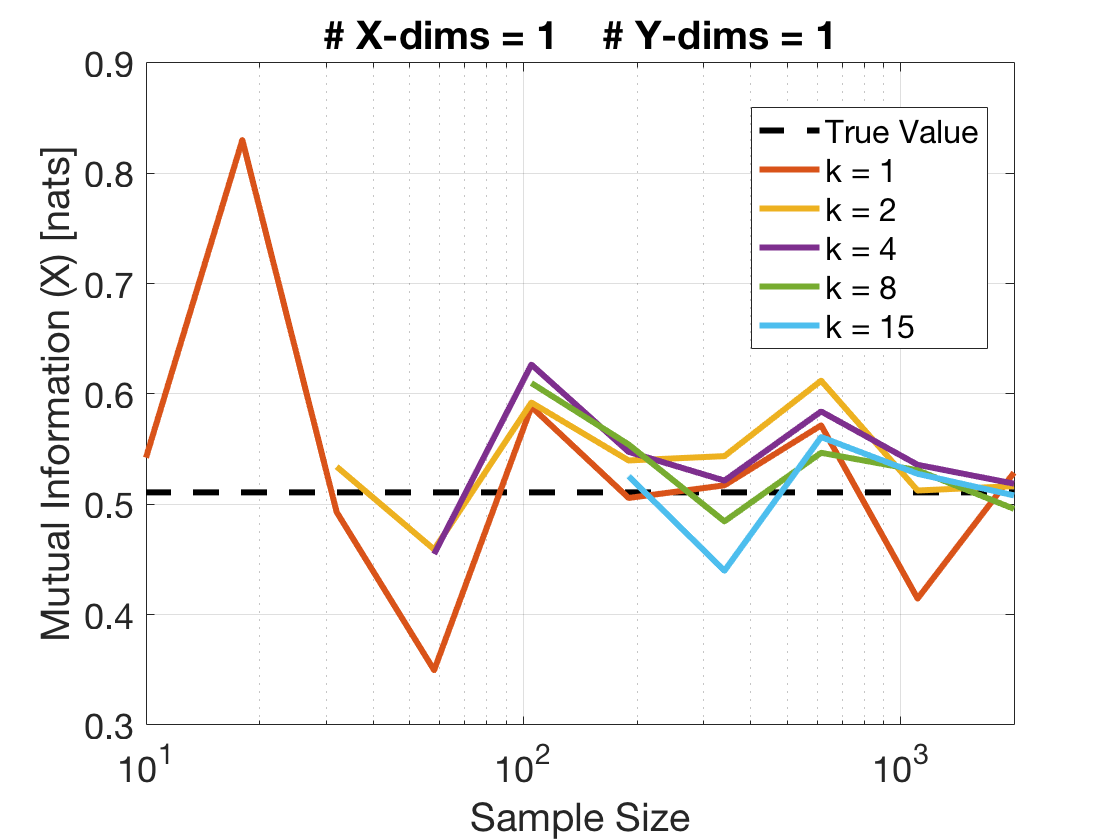

% Initialize a figure for plotting entropy estimates:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
% set(gcf,'position',[1,1,1000,350]);

% Plot mutual information values:
plotTrue  = plot([nSampleSizes(1),sampleSizes(end)],[iTrue,iTrue],'k--','linewidth',3); hold on;
for k = 1:nNeighbors
    plotColor = mod(k,7)+1;
    plotkNN(k,:) = plot(sampleSizes,squeeze(ikNN(:,k,:)),'color',colors(plotColor,:),'linewidth',3); 
    hold on;
end

% Aesthetics:
set(gca,'Xscale','log')
legendCell = cellstr(num2str(neighbors','k = %-d'));
legend([plotTrue;plotkNN(:,1)],[{'True Value'};legendCell],'location','best')
xlabel('Sample Size')
ylabel('Mutual Information (X) [nats]')
title(sprintf('# X-dims = %d    # Y-dims = %d',xMarginals,yMarginals))
set(gca,'fontsize',18);
grid on;